clc; clear all;


function u = sigmoid(x, a)
    % This function defines a smooth saturation, modeled by a sigmoid
    % function that saturates at the value 2/a.
        u = 2.*(1-exp(-a.*x))./(a.*(1+exp(-a.*x)));
end

function du = dsigmoid_ref(x, a)
    % This function returns the derivative of the sigmoid function with
    % respect to x, evaluated at x.
    du = 4.*exp(-a.*x)./(1+exp(-a.*x)).^2;
end


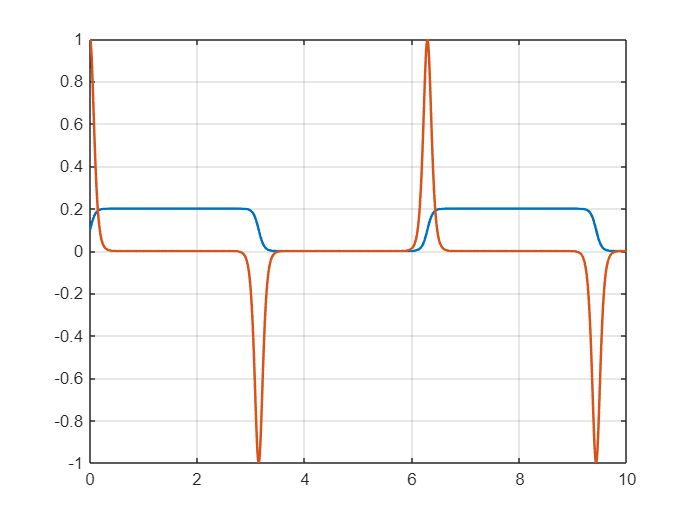

Ts = 0.01;
Tsim = 10;

% Define the time vector
t_vec = 0:Ts:Tsim;
num_steps = length(t_vec);

% Smooth pulse signal
bias = 0.1;
sat = 2/0.1;
amplitude = 0.24;


amplitude = 1;
r(1,:) = sigmoid(amplitude.*sin(t_vec), sat) + bias;

r_dot(1,:) = dsigmoid_ref(amplitude.*sin(t_vec), sat).*amplitude.*cos(t_vec);

figure();
plot(t_vec, r, ...
    t_vec, r_dot)